# Controllers Design


$$M=k\sqrt{L_1 L_2 }=\;k\;\sqrt{L\cdot \frac{L}{2\ldotp 33}}=k\;\frac{L}{\sqrt{2\ldotp 33}}\;\;\;\;$$


### Dataset Upload

clc; clear all; close all

L_nom = 36.5e-6;
Lm_nom = 0.99*L_nom/sqrt(2.33);
C_nom = 100e-06;


load("dataset\20_30.mat"); C1 = C; k1 = k; Lm1 = k1*L_nom/sqrt(2.33);
load("dataset\25_35.mat"); C2 = C; k2 = k; Lm2 = k2*L_nom/sqrt(2.33);
load("dataset\30_35_40.mat"); C3 = C; k3 = k; Lm3 = k3*L_nom/sqrt(2.33);
load("dataset\45_50_60.mat"); C4 = C; k4 = k; Lm4 = k4*L_nom/sqrt(2.33);

Lm_bm = mean([Lm1, Lm2, Lm3, Lm4]);
C_bm = mean([C1, C2, C3, C4]);

fprintf('Variation to Real Value\n Lm: %0.3f %%\t C: %0.3f %%', (1-Lm_bm/Lm_nom)*100, (1-C_bm/C_nom)*100);

Variation to Real Value
 Lm: 33.533 %	 C: -19.428 %

### System Definition

DuCy=20; 
I_Lo=0; V_Co=0;
Vg=5; Vd=0;
Vs=[Vg Vd];
X=[I_Lo V_Co];


[A,B,C,D,G_nom] =flyback_ss(Vs,X,DuCy,Lm_bm,C_bm);
G_nom

G_nom =
 
            2.17e10
  ---------------------------
  s^2 + 1.271e04 s + 3.539e10
 
Continuous-time transfer function.



bode(G_nom)


### Internal Model Control

s=tf('s');
lambda = 10*exp(-5);
n = 2;

F = 1/(lambda*s+1)^n;
Gc = (1/G)*F

Gc =
 
                                
  s^4 + 8e05 s^3 + 5.792e13 s^2 
                                
          + 2.31e19 s           
                                
                  + 8.341e26    
                                
  ------------------------------
                              
    454 s^5 + 4.85e10 s^4     
                              
            + 3.244e16 s^3    
                              
            + 1.395e24 s^2    
                              
            + 4.142e25 s      
                              
                    + 3.073e26
                              
 
Continuous-time transfer function.



### Lag-Lead Compensator

% Step 1: Uncompensated system Bode plot
s = tf('s');
%G = 1 / (s * (s + 3));  % Example transfer function, replace with your own
[Gm,Pm, ~, crossover_freq] = margin(G);  % Get current gain crossover frequency

% Step 2: Choose new gain crossover frequency
new_crossover_freq = crossover_freq / 10;  % Choose new crossover frequency one decade below

% Step 3: Determine beta and other corner frequency
desired_phase_margin = 60;  % Desired phase margin in degrees
desired_gain_margin = 4;  % Desired gain margin in dB
attenuation = -20 * log10(sqrt((1 + sin(desired_phase_margin*pi/180))^2 / (1 - sin(desired_phase_margin*pi/180))^2))

attenuation = -22.8779

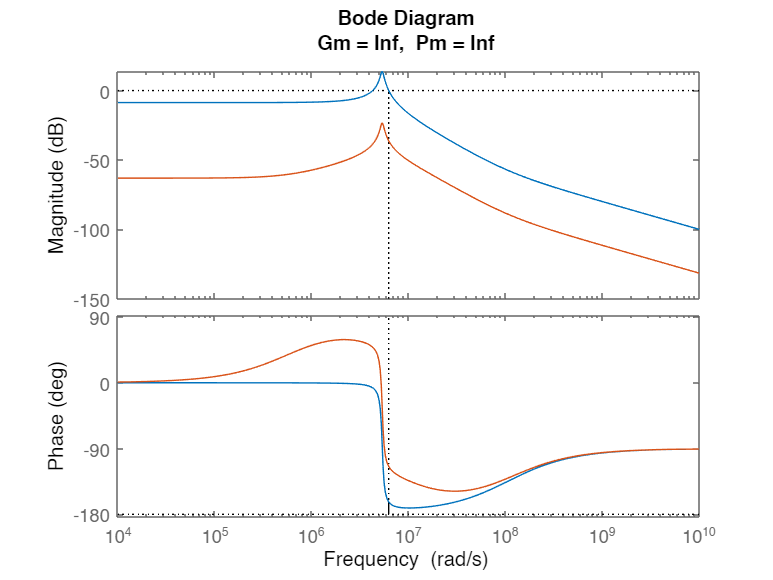


beta = 10^(-attenuation / 20);  % Compute beta from attenuation
T = 1 / (beta * new_crossover_freq);  % Compute T from beta and new crossover frequency

% Step 4: Calculate Kc
K = abs(dcgain(G));  % Get the DC gain of the uncompensated system
Kc = K / beta;  % Calculate the compensator gain

% Create the lag compensator transfer function
Gc = Kc * ((s + 1 / (T * beta)) / (s + 1 / T));

margin(G)
hold on
% Step 1 (revisited): Compensated system Bode plot
margin(G * Gc);  % Plot Bode diagram and compute gain/phase margin
hold off

### Lag-Lead compensator

% Desired phase and gain margins
desired_phase_margin = 60; % in degrees
desired_gain_margin = 6; % in dB

% Plant transfer function
s = tf('s');

% Calculate the poles and damping factors
[~, ~, poles] = damp(G);
% Find the index of the dominant pole
[~, index] = min(abs(real(poles)));
% Select the dominant pole
dominant_pole = -poles(index)

dominant_pole = 2.0000e+05 - 5.3703e+06i

w = abs(dominant_pole)

w = 5.3740e+06

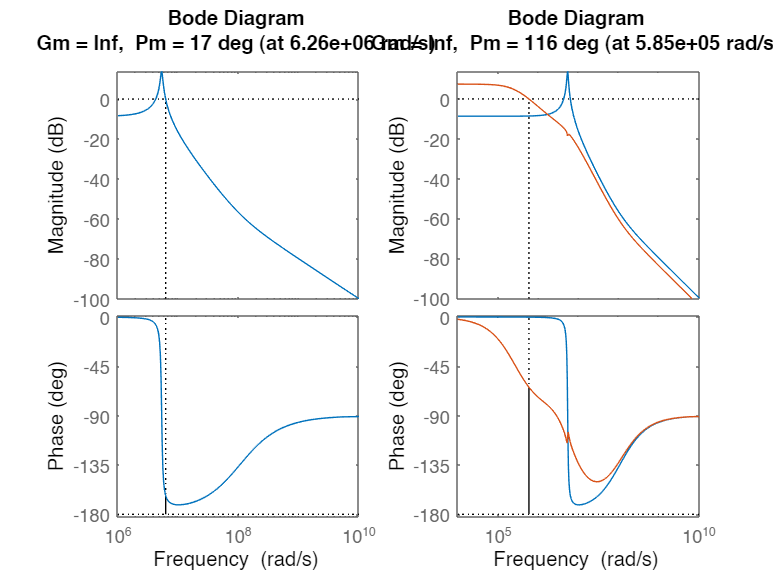

T = 1/(w/20);
tau = 1/(w/2);

C_lag = (tau*s + 1)/(T*s + 1);

wc = 600000;
K = 1/abs(freqresp(C_lag*G,wc));
C_lag = K*C_lag;

wn=5370000;
xci_z=0.03; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.9;
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);

figure
subplot(1,2,1)
margin(G)
subplot(1,2,2)
bode(G)
hold on
margin(G*C_lag*notch)
hold off

getPeakGain(feedback(1,G*C_lag*notch))

ans = 1.0514

### PI Controller with Notch Filter

Vorrei un $\omega_c$ prossima all'antirisonanza (che è attorno a 100 rad/s)

wc=190970; % Desired Omega

L'azione integrale mi sfasa, la metto almeno una decade prima.

wi=wc/0.1; % pulsazione azione integrale
Ti=1/wi;

Il mio controllore sarà


$$C(s)=K_p \left(1+1/(Ti\cdot s)\right)=K_p C_o(s)$$


con $C_o(s)=$

s=tf('s');
Co=1+1/(Ti*s);

Calcolo $K_p$ in modo che $C(s)*P(s)=K_p \left(C_o(s)*P(s)\right)$ abbia modulo 1 in $\omega_c$. 

$|K_p \left(C_o(j\omega_c)*P(j\omega_c)\right)|=1 $ quindi $K_p=1/| \left(C_o(j\omega_c)*P(j\omega_c)\right)|$

Kp=1/abs(freqresp(Co*G,wc));
C_old=Kp*Co

C_old =
 
  1.412e-07 s + 0.2697
  --------------------
      5.236e-07 s
 
Continuous-time transfer function.



#### Notch filter

damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.00e+05 + 5.37e+06i     3.72e-02       5.37e+06         5.00e-06    
 -2.00e+05 - 5.37e+06i     3.72e-02       5.37e+06         5.00e-06    
 -2.00e+05 + 5.37e+06i     3.72e-02       5.37e+06         5.00e-06    
 -2.00e+05 - 5.37e+06i     3.72e-02       5.37e+06         5.00e-06    


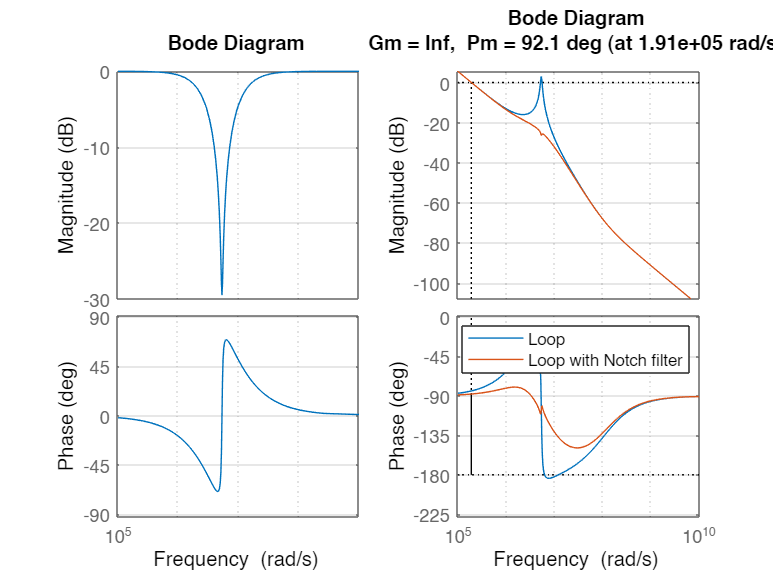

wn=5370000;
xci_z=0.03; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.9;
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
figure
subplot(1,2,1)
bode(notch)
grid on
Kp=1/abs(freqresp(Co*G*notch,wc));
c=Kp*Co*notch;

subplot(1,2,2)
bode(C_old*G); hold on
margin(c*G); hold off
grid on
legend('Loop','Loop with Notch filter')

getPeakGain(feedback(1,c*G))

ans = 1.0118